                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                    [https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html)

data = table2array(readtable('../../data/data1/CHID46.csv'));
dpi = data(:,1);
y = data(:,2);
num_pat = 1;

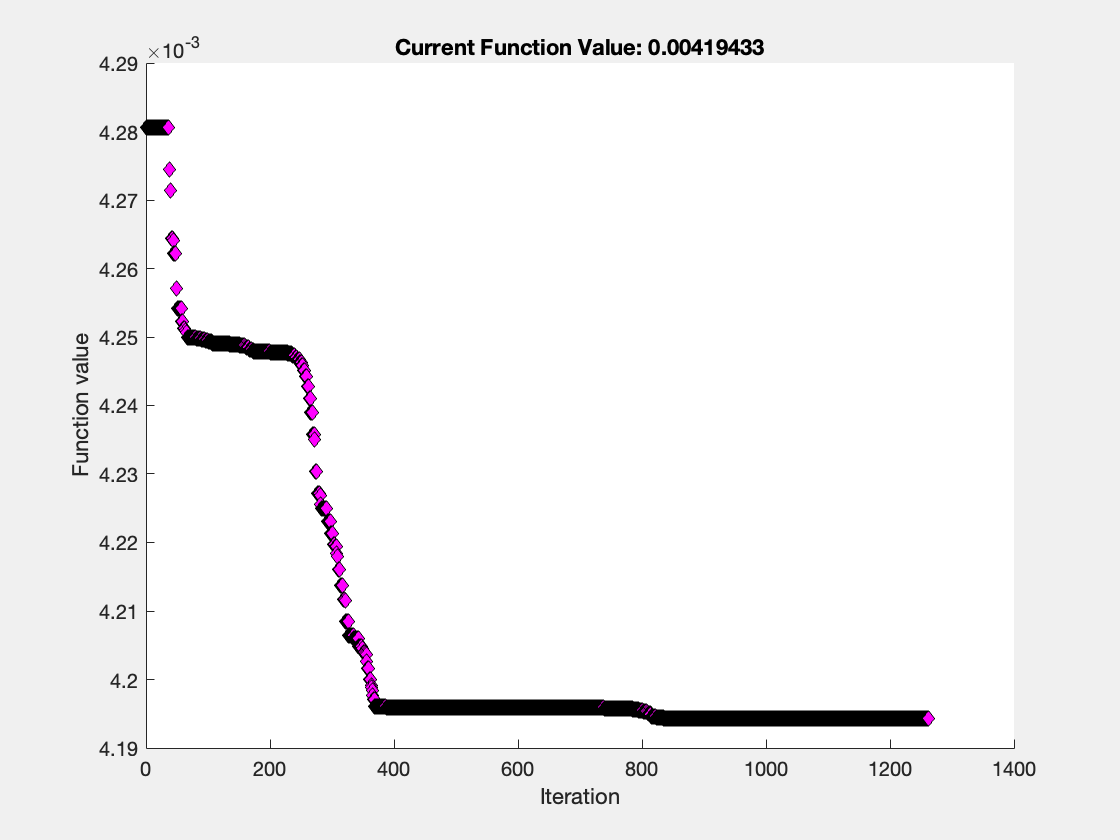

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.004194 



bp = 1.0e+04 *

    0.0000    0.0000    0.0000    0.0002    4.0734    0.0000    0.0006


fval = 0.0042

% params = table2array(readtable('first10v2.csv'));

% x0 = [1.0017e-05    1.9549e-06    5.891    0.40695    488.16    0.47094    30] 
% J(x0, 0:0.01:dpi(end),[10^4 0 10^-3],0.01, dpi,y)


x1 = [2.0209E-7 1.2719E-7 0.41184 1.52453 41085.62299 0.03901 6];
[bp, fval] = best_param(x1,dpi,y)

% for i = 1:7
%     bp(i)
% 
% end


% x0 = [5.2573E-7    2.1501E-7    0.12071    0.77157  14257.02649   0.03465   0.10001] 

x0 = 1.0e+04 *

    0.0000    0.0000    0.0000    0.0001    1.4257    0.0000    0.0000


% J(x0, 0:0.01:dpi(end),[10^4 0 10^-3],0.01, dpi,y)

ans = 0.0086

 x0 = [4.3106E-7    1.9577E-7    0.19179    0.91266  19013.74588   0.03308   1.00118] 

x0 = 1.0e+04 *

    0.0000    0.0000    0.0000    0.0001    1.9014    0.0000    0.0001


 J(x0, 0:0.01:dpi(end),[10^4 0 10^-3],0.01, dpi,y)

ans = 0.0059



  x0 = [4.0434E-7  1.7254E-7    0.18514   1.03289  22913.48128  0.03536   4.0498E-14] 

x0 = 1.0e+04 *

    0.0000    0.0000    0.0000    0.0001    2.2913    0.0000    0.0000


 J(x0, 0:0.01:dpi(end),[10^4 0 10^-3],0.01, dpi,y)

ans = 0.0054

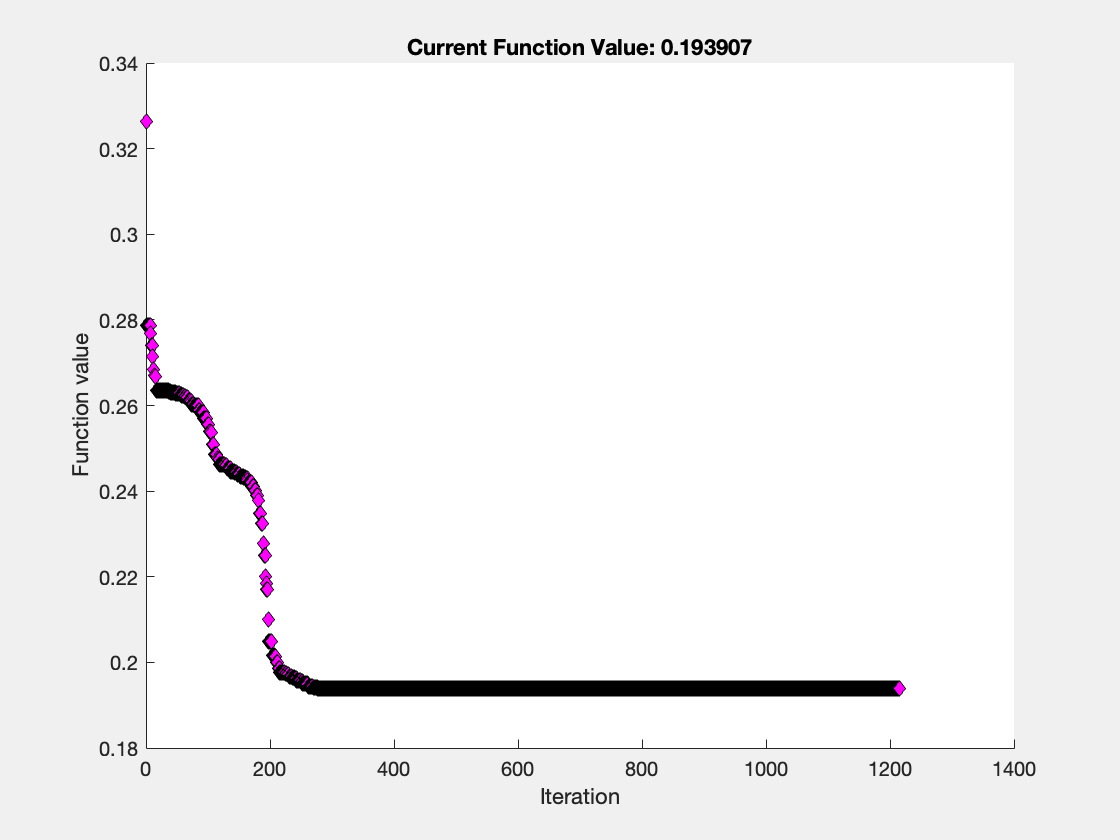

Optimization terminated prematurely by user.


bp = 1.0e+03 *

    0.0000    0.0000    0.0088    0.0011    8.3483    0.0001    0.0291


fval = 0.1939

tic
% x0 = [1.3909e-06    9.6352e-07    9.0631    0.78948    3869.8    1.6615    13];
% x0 = [1.1463e-06    7.452e-07    16.375    0.26922    4374.2    0.20209     7];
% x0 = params(1,2:end);
% x0
% 
N = 1;
out = zeros(N,8);
lb = [0.2*10^-5 10^-7 0 0 0 0 1];
ub = [2*10^-5 2*10^-6 20 1 10^4 1 30];
for i=1:N
    x0 = params(i,2:end);
    [bp, fval] = best_param(x0,dpi,y) %,lb,ub)
    out(i,1) = fval;
    out(i,2:end) = bp;
end 

% % disp(bp);
% % disp(J(bp, 0:0.01:dpi(end),[10^4 0 10^-3],0.01, dpi,y));
% % disp(J(x0, 0:0.01:dpi(end),[10^4 0 10^-3],0.01, dpi,y))


toc

Elapsed time is 64.145027 seconds.


out

out = 1.0e+03 *

         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
    0.0003    0.0000    0.0000    0.0034    0.0036    4.7690    0.0007    0.0292


tic
% x0 = [1.3909e-06    9.6352e-07    9.0631    0.78948    3869.8    1.6615    13];
% x0 = [1.1463e-06    7.452e-07    16.375    0.26922    4374.2    0.20209     7];
% x0 = params(1,2:end);
% x0
% 
% N = 10;
% out = zeros(N,8);
% lb = [0.2*10^-5 10^-7 0 0 0 0 1];
% % ub = [2*10^-5 2*10^-6 20 1 10^4 1 30];
% ub = [];
% for i=1:N
%     x0 = params(i,2:end);
%     [bp, fval] = best_param2(x0,dpi,y,lb,ub);
%     out(N,1) = fval;
%     out(N,2:end) = bp;
%     disp([params(i,1),fval]);
% end 
% % disp(bp);
% % disp(J(bp, 0:0.01:dpi(end),[10^4 0 10^-3],0.01, dpi,y));
% % disp(J(x0, 0:0.01:dpi(end),[10^4 0 10^-3],0.01, dpi,y))


toc

Elapsed time is 0.001077 seconds.


%% decay function 

function out=b(t,b0,bi,k,tau)
    if t <= tau
        out = b0;
    else
        out = bi+(b0-bi)*exp(-k*(t-tau));
    end
end


function out = pred(ti,init,b0,bi,k,dlt,p,d,tau)

    f = @(t,x) [d*(init(1)-x(1))-b(t,b0,bi,k,tau)*x(1)*x(3);...
            b(t,b0,bi,k,tau)*x(1)*x(3)-dlt*x(2);...
            p*x(2)-23*x(3) ];    

    [t,xa] = ode45(f,ti,init);
    out = xa;
 
end



function out=pred_logV(init,b0,bi,k,dlt,p,d,tau,h,dpi)
    V = zeros(dpi(end)/h+1,1);
    start = 0;
    for i = 1:size(dpi,1)

        sti = start:h:dpi(i);
        xa = pred(sti,init,b0,bi,k,dlt,p,d,tau);

        idx = round(sti/h+1);
        V(idx) = xa(:,3);
        start = dpi(i);
        init = xa(end,:);
    end 
    out = log10(V);

end 

function out=J(params, ti,init,h, dpi,y)
    
    b0 = params(1);
    bi = params(2);
    k = params(3);
    dlt = params(4);
    p = params(5);
    d = params(6);
    tau = params(7);

    xa = pred(ti,init,b0,bi,k,dlt,p,d,tau);
    V = xa(:,3);

    y_hat = log10(V(dpi/h+1));
    out =  1/size(y,1) *sum((y-y_hat).^2);
end 

function [x,fval]=best_param(x0,dpi,y) %,lb,ub)
    h = 0.01;
    ti = 0:h:dpi(end); 
    init = [10^4 0 10^-3];

    options = optimset('PlotFcns','optimplotfval','TolFun',1e-7,'TolX',1e-7,'MaxFunEvals', 2000);
    JJ = @(params) J(params, ti,init,h, dpi,y); 
%     [x,fval] = fminsearchbnd(JJ,x0,lb,ub,options);
    [x,fval] = fminsearch(JJ,x0,options);
end 

function [x,fval]=best_param2(x0,dpi,y,lb,ub)
    h = 0.01;
    ti = 0:h:dpi(end); 
    init = [10^4 0 10^-3];

    options = optimset('PlotFcns','optimplotfval','TolX',1e-7,'MaxFunEvals', 1800);
    JJ = @(params) J(params, ti,init,h, dpi,y); 
    [x,fval] = fmincon(JJ,x0,[],[],[],[],lb,ub,[],options);
end 




function [x,fval,exitflag,output] = fminsearchbnd(fun,x0,LB,UB,options,varargin)
% FMINSEARCHBND: FMINSEARCH, but with bound constraints by transformation
% usage: x=FMINSEARCHBND(fun,x0)
% usage: x=FMINSEARCHBND(fun,x0,LB)
% usage: x=FMINSEARCHBND(fun,x0,LB,UB)
% usage: x=FMINSEARCHBND(fun,x0,LB,UB,options)
% usage: x=FMINSEARCHBND(fun,x0,LB,UB,options,p1,p2,...)
% usage: [x,fval,exitflag,output]=FMINSEARCHBND(fun,x0,...)
% 
% arguments:
%  fun, x0, options - see the help for FMINSEARCH
%
%  LB - lower bound vector or array, must be the same size as x0
%
%       If no lower bounds exist for one of the variables, then
%       supply -inf for that variable.
%
%       If no lower bounds at all, then LB may be left empty.
%
%       Variables may be fixed in value by setting the corresponding
%       lower and upper bounds to exactly the same value.
%
%  UB - upper bound vector or array, must be the same size as x0
%
%       If no upper bounds exist for one of the variables, then
%       supply +inf for that variable.
%
%       If no upper bounds at all, then UB may be left empty.
%
%       Variables may be fixed in value by setting the corresponding
%       lower and upper bounds to exactly the same value.
%
% Notes:
%
%  If options is supplied, then TolX will apply to the transformed
%  variables. All other FMINSEARCH parameters should be unaffected.
%
%  Variables which are constrained by both a lower and an upper
%  bound will use a sin transformation. Those constrained by
%  only a lower or an upper bound will use a quadratic
%  transformation, and unconstrained variables will be left alone.
%
%  Variables may be fixed by setting their respective bounds equal.
%  In this case, the problem will be reduced in size for FMINSEARCH.
%
%  The bounds are inclusive inequalities, which admit the
%  boundary values themselves, but will not permit ANY function
%  evaluations outside the bounds. These constraints are strictly
%  followed.
%
%  If your problem has an EXCLUSIVE (strict) constraint which will
%  not admit evaluation at the bound itself, then you must provide
%  a slightly offset bound. An example of this is a function which
%  contains the log of one of its parameters. If you constrain the
%  variable to have a lower bound of zero, then FMINSEARCHBND may
%  try to evaluate the function exactly at zero.
%
%
% Example usage:
% rosen = @(x) (1-x(1)).^2 + 105*(x(2)-x(1).^2).^2;
%
% fminsearch(rosen,[3 3])     % unconstrained
% ans =
%    1.0000    1.0000
%
% fminsearchbnd(rosen,[3 3],[2 2],[])     % constrained
% ans =
%    2.0000    4.0000
%
% See test_main.m for other examples of use.
%
%
% See also: fminsearch, fminspleas
%
%
% Author: John D'Errico
% E-mail: woodchips@rochester.rr.com
% Release: 4
% Release date: 7/23/06
% size checks
xsize = size(x0);
x0 = x0(:);
n=length(x0);
if (nargin<3) || isempty(LB)
  LB = repmat(-inf,n,1);
else
  LB = LB(:);
end
if (nargin<4) || isempty(UB)
  UB = repmat(inf,n,1);
else
  UB = UB(:);
end
if (n~=length(LB)) || (n~=length(UB))
  error 'x0 is incompatible in size with either LB or UB.'
end
% set default options if necessary
if (nargin<5) || isempty(options)
  options = optimset('fminsearch');
end
% stuff into a struct to pass around
params.args = varargin;
params.LB = LB;
params.UB = UB;
params.fun = fun;
params.n = n;
% note that the number of parameters may actually vary if 
% a user has chosen to fix one or more parameters
params.xsize = xsize;
params.OutputFcn = [];
% 0 --> unconstrained variable
% 1 --> lower bound only
% 2 --> upper bound only
% 3 --> dual finite bounds
% 4 --> fixed variable
params.BoundClass = zeros(n,1);
for i=1:n
  k = isfinite(LB(i)) + 2*isfinite(UB(i));
  params.BoundClass(i) = k;
  if (k==3) && (LB(i)==UB(i))
    params.BoundClass(i) = 4;
  end
end
% transform starting values into their unconstrained
% surrogates. Check for infeasible starting guesses.
x0u = x0;
k=1;
for i = 1:n
  switch params.BoundClass(i)
    case 1
      % lower bound only
      if x0(i)<=LB(i)
        % infeasible starting value. Use bound.
        x0u(k) = 0;
      else
        x0u(k) = sqrt(x0(i) - LB(i));
      end
      
      % increment k
      k=k+1;
    case 2
      % upper bound only
      if x0(i)>=UB(i)
        % infeasible starting value. use bound.
        x0u(k) = 0;
      else
        x0u(k) = sqrt(UB(i) - x0(i));
      end
      
      % increment k
      k=k+1;
    case 3
      % lower and upper bounds
      if x0(i)<=LB(i)
        % infeasible starting value
        x0u(k) = -pi/2;
      elseif x0(i)>=UB(i)
        % infeasible starting value
        x0u(k) = pi/2;
      else
        x0u(k) = 2*(x0(i) - LB(i))/(UB(i)-LB(i)) - 1;
        % shift by 2*pi to avoid problems at zero in fminsearch
        % otherwise, the initial simplex is vanishingly small
        x0u(k) = 2*pi+asin(max(-1,min(1,x0u(k))));
      end
      
      % increment k
      k=k+1;
    case 0
      % unconstrained variable. x0u(i) is set.
      x0u(k) = x0(i);
      
      % increment k
      k=k+1;
    case 4
      % fixed variable. drop it before fminsearch sees it.
      % k is not incremented for this variable.
  end
  
end
% if any of the unknowns were fixed, then we need to shorten
% x0u now.
if k<=n
  x0u(k:n) = [];
end
% were all the variables fixed?
if isempty(x0u)
  % All variables were fixed. quit immediately, setting the
  % appropriate parameters, then return.
  
  % undo the variable transformations into the original space
  x = xtransform(x0u,params);
  
  % final reshape
  x = reshape(x,xsize);
  
  % stuff fval with the final value
  fval = feval(params.fun,x,params.args{:});
  
  % fminsearchbnd was not called
  exitflag = 0;
  
  output.iterations = 0;
  output.funcCount = 1;
  output.algorithm = 'fminsearch';
  output.message = 'All variables were held fixed by the applied bounds';
  
  % return with no call at all to fminsearch
  return
end
% Check for an outputfcn. If there is any, then substitute my
% own wrapper function.
if ~isempty(options.OutputFcn)
  params.OutputFcn = options.OutputFcn;
  options.OutputFcn = @outfun_wrapper;
end
% now we can call fminsearch, but with our own
% intra-objective function.
[xu,fval,exitflag,output] = fminsearch(@intrafun,x0u,options,params);
% undo the variable transformations into the original space
x = xtransform(xu,params);
% final reshape to make sure the result has the proper shape
x = reshape(x,xsize);
% Use a nested function as the OutputFcn wrapper
  function stop = outfun_wrapper(x,varargin);
    % we need to transform x first
    xtrans = xtransform(x,params);
    
    % then call the user supplied OutputFcn
    stop = params.OutputFcn(xtrans,varargin{1:(end-1)});
    
  end
end % mainline end
% ======================================
% ========= begin subfunctions =========
% ======================================
function fval = intrafun(x,params)
% transform variables, then call original function
% transform
xtrans = xtransform(x,params);
% and call fun
fval = feval(params.fun,reshape(xtrans,params.xsize),params.args{:});
end % sub function intrafun end
% ======================================
function xtrans = xtransform(x,params)
% converts unconstrained variables into their original domains
xtrans = zeros(params.xsize);
% k allows some variables to be fixed, thus dropped from the
% optimization.
k=1;
for i = 1:params.n
  switch params.BoundClass(i)
    case 1
      % lower bound only
      xtrans(i) = params.LB(i) + x(k).^2;
      
      k=k+1;
    case 2
      % upper bound only
      xtrans(i) = params.UB(i) - x(k).^2;
      
      k=k+1;
    case 3
      % lower and upper bounds
      xtrans(i) = (sin(x(k))+1)/2;
      xtrans(i) = xtrans(i)*(params.UB(i) - params.LB(i)) + params.LB(i);
      % just in case of any floating point problems
      xtrans(i) = max(params.LB(i),min(params.UB(i),xtrans(i)));
      
      k=k+1;
    case 4
      % fixed variable, bounds are equal, set it at either bound
      xtrans(i) = params.LB(i);
    case 0
      % unconstrained variable.
      xtrans(i) = x(k);
      
      k=k+1;
  end
end
end % sub function xtransform end
